clear
syms t Theta_1(t) Theta_2(t) Theta_3(t) R_1(t)


syms r_1 r_1y r_2 r_3 x

syms V_r omega_1 omega_2 omega_3 theta_1 theta_2 theta_3 

syms a_r alpha_1 alpha_2 alpha_3


Vr_2=0.75

Vr_2 = 0.7500

Vr_3=1.70

Vr_3 = 1.7000

Vr_1y=0.45

Vr_1y = 0.4500


Vtheta_2=30*sym(pi)/180

$$Vtheta\_2 = \frac{\pi }{6}$$

Vomega_2=20

Vomega_2 = 20

Valpha_2=0

Valpha_2 = 0



Fc=sin(Theta_1)*R_1-r_1y;
Fc=simplify(Fc,'Steps',5)

$$Fc(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{\mathrm{1y}}$$


fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1])

$$fc(t) = r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}$$

SolR_1=solve(fc,r_1)

$$SolR\_1 = \frac{r_{\mathrm{1y}}}{\sin\left(\theta_{1}\right)}$$


Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5)

$$Fx(t) = r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)+r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)$$


fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-\frac{r_{\mathrm{1y}}\,\cos\left(\theta_{1}\right)}{\sin\left(\theta_{1}\right)}$$

fx=simplify(fx,'Steps',5)

$$fx = r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)$$

SolTheta_1=solve(fx,theta_1)

$$SolTheta\_1 = \mathrm{acot}\left(\frac{r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)}{r_{\mathrm{1y}}}\right)$$



Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5)

$$Fy(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)$$


fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fy = r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right)$$


SolTheta_3=solve(fy,theta_3);
SolTheta_3=SolTheta_3(1)

$$SolTheta\_3 = \mathrm{asin}\left(\frac{r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)}{r_{3}}\right)$$


DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F1 = \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F2 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F3 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$



D2FcDt2=diff(DFcDt)

$$D2FcDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$

D2FxDt2=diff(DFxDt)

$$D2FxDt2(t) = \cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}$$

D2FyDt2=diff(DFyDt)

$$D2FyDt2(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}R_{1}\left(t\right)+r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{2}\left(t\right)\right)}^{2}+r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\Theta_{3}\left(t\right)\right)}^{2}-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{2}\left(t\right)-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{3}\left(t\right)-\sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,{\left(\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\right)}^{2}+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\Theta_{1}\left(t\right)+2\,\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)$$


F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F4 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F5 = r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F6 = -r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$


fP(r_1,theta_1,theta_3)=[fc;fx;fy]

$$fP(r\_1, theta\_1, theta\_3) = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

fP=subs(fP,[theta_2,r_1y,r_2,r_3],[Vtheta_2,Vr_1y,Vr_2,Vr_3])

$$fP(r\_1, theta\_1, theta\_3) = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10} \end{array}\right)$$

fP=simplify(fP,'Steps',5)

$$fP(r\_1, theta\_1, theta\_3) = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-\frac{9}{20}\\ \frac{17\,\cos\left(\theta_{3}\right)}{10}-\frac{9\,\cot\left(\theta_{1}\right)}{20}+\frac{3\,\sqrt{3}}{8}\\ \frac{3}{40}-\frac{17\,\sin\left(\theta_{3}\right)}{10} \end{array}\right)$$



valTheta_3=subs(SolTheta_3,[theta_2,r_2,r_3,r_1y],[Vtheta_2,Vr_2,Vr_3,Vr_1y]);
ValTheta_1=subs(SolTheta_1,[theta_2,r_2,r_3,r_1y,theta_3],[Vtheta_2,Vr_2,Vr_3,Vr_1y,valTheta_3]);
valR_1=subs(SolR_1,[r_1y,theta_1],[Vr_1y,ValTheta_1]);


JacP=jacobian(fP, [r_1,theta_1,theta_3])

$$JacP(r\_1, theta\_1, theta\_3) = \left(\begin{array}{ccc} \sin\left(\theta_{1}\right) & r_{1}\,\cos\left(\theta_{1}\right) & 0\\ 0 & \frac{9\,{\cot\left(\theta_{1}\right)}^{2}}{20}+\frac{9}{20} & -\frac{17\,\sin\left(\theta_{3}\right)}{10}\\ 0 & 0 & -\frac{17\,\cos\left(\theta_{3}\right)}{10} \end{array}\right)$$

JacInvP=JacP^-1;

pP=[2 0.1 0.1]';
ValoresNR(1,:)=pP';

iteraciones=15;
for i=1:iteraciones
    pP=double(pP-JacInvP(pP(1),pP(2),pP(3))*fP(pP(1),pP(2),pP(3)));
    ValoresNR(i+1,:)=double(pP)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end



ValoresNR

ValoresNR =     2.0000    0.1000    0.1000
    3.5652    0.1473    0.0440
    2.2782    0.1801    0.0441
    2.4019    0.1889    0.0441
    2.3906    0.1894    0.0441
    2.3906    0.1894    0.0441


NormErrorNR'

ans =     1.5669
    1.2874
    0.1240
    0.0113
    0.0000


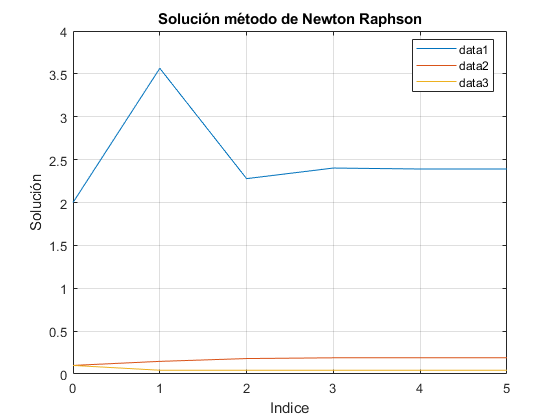

figure()
plot(0:(length(ValoresNR(:,1))-1),ValoresNR)
title('Solución método de Newton Raphson')
legend('show',"Location","best")
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresNR))
grid on

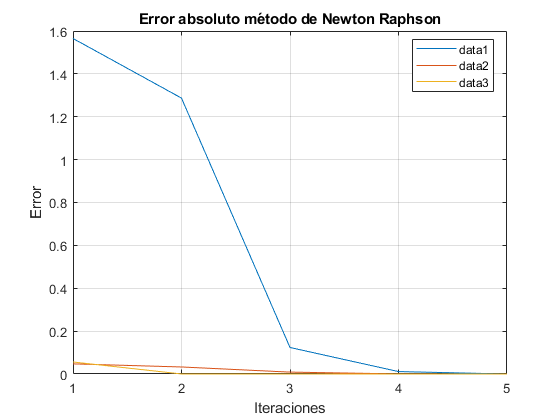

figure()
plot(ErrorNR)
title('Error absoluto método de Newton Raphson')
legend('show',"Location","best")
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on

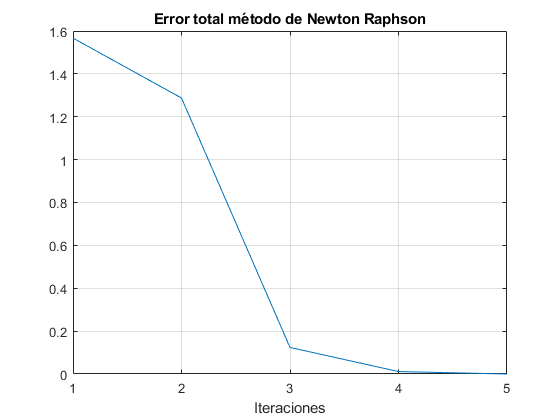

figure()
plot(NormErrorNR)
title('Error total método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on


SolPosNR=double(pP)

SolPosNR =     2.3906
    0.1894
    0.0441



F=[fc,fx,fy].'

$$F(t) = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

Pi=[2 0.1 0.1]

Pi =     2.0000    0.1000    0.1000


Vi=[Vr_1y,Vr_2,Vr_3]

Vi =     0.4500    0.7500    1.7000



[Sol,Error]= NR_Sistema_extenso(F,Pi,Vi,Vtheta_2,Vomega_2,Valpha_2)

$$ans = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} r_{1}\,\sin\left(\theta_{1}\right)-r_{\mathrm{1y}}\\ r_{2}\,\cos\left(\theta_{2}\right)+r_{3}\,\cos\left(\theta_{3}\right)-r_{\mathrm{1y}}\,\cot\left(\theta_{1}\right)\\ r_{\mathrm{1y}}-r_{2}\,\sin\left(\theta_{2}\right)-r_{3}\,\sin\left(\theta_{3}\right) \end{array}\right)$$

Error using sym/subsindex (line 857)
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Error in untitled>NR_Sistema_extenso (line 180)
fP(r_1,theta_1,theta_3)=F(1:3)




ErrorNRFinal=double(NormErrorNR(end))

### Velocidad

fV(V_r,omega_1,omega_3)=[F1;F2;F3]

$$fV(V\_r, omega\_1, omega\_3) = \left(\begin{array}{c} \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}\right)$$

fV=subs(fV,[theta_2,r_1y,r_2,r_3,r_1,theta_1,theta_3,omega_2],[Vtheta_2,Vr_1y,Vr_2,Vr_3,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2])

$$fV(V\_r, omega\_1, omega\_3) = \begin{array}{l} \left(\begin{array}{c} \frac{672893857359465\,\omega_{1}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}-V_{r}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)-\frac{17\,\omega_{3}\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{10}-\frac{15}{2}\\ V_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)-\frac{15\,\sqrt{3}}{2}+\sigma_{1}-\frac{17\,\omega_{3}\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{10}\\ V_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{672893857359465\,\omega_{1}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656} \end{array}$$

fV=simplify(fV,'Steps',5)

$$fV(V\_r, omega\_1, omega\_3) = \begin{array}{l} \left(\begin{array}{c} \frac{672893857359465\,\omega_{1}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}-V_{r}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)-\frac{17\,\omega_{3}\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{10}-\frac{15}{2}\\ V_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)-\frac{15\,\sqrt{3}}{2}+\sigma_{1}-\frac{17\,\omega_{3}\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{10}\\ V_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{672893857359465\,\omega_{1}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656} \end{array}$$


JacV=jacobian(fV, [V_r,omega_1,omega_3]);
JacInvV=JacV^-1;

pV=[2 0.1 0.1]';
ValoresVNR(1,:)=pV';

iteraciones=15;
for i=1:iteraciones
    pV=double(pV-JacInvV(pV(1),pV(2),pV(3))*fV(pV(1),pV(2),pV(3)));
    ValoresVNR(i+1,:)=double(pV)';
    ErrorNR(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end


SolVelNR=double(pV)

SolVelNR =    -6.8025
    0.5454
   -7.6488


fA(a_r,alpha_1,alpha_3)=[F4;F5;F6]

$$fA(a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}+\sigma_{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}\\ r_{1}\,\cos\left(\theta_{1}\right)\,{\omega_{1}}^{2}+2\,V_{r}\,\sin\left(\theta_{1}\right)\,\omega_{1}-r_{2}\,\cos\left(\theta_{2}\right)\,{\omega_{2}}^{2}-r_{3}\,\cos\left(\theta_{3}\right)\,{\omega_{3}}^{2}-a_{r}\,\cos\left(\theta_{1}\right)+\alpha_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-\alpha_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ -\sigma_{1}+\sigma_{2}+r_{2}\,\sin\left(\theta_{2}\right)\,{\omega_{2}}^{2}+r_{3}\,\sin\left(\theta_{3}\right)\,{\omega_{3}}^{2}+a_{r}\,\sin\left(\theta_{1}\right)+\sigma_{3}-\alpha_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\alpha_{3}\,r_{3}\,\cos\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{1}\,\sin\left(\theta_{1}\right)\,{\omega_{1}}^{2}\\ \sigma_{2}=2\,V_{r}\,\cos\left(\theta_{1}\right)\,\omega_{1}\\ \sigma_{3}=\alpha_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}$$

fA=subs(fA,[theta_2,r_1y,r_2,r_3,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,Vr_1y,Vr_2,Vr_3,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2])

$$fA(a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\sigma_{3}-\sigma_{2}+\sigma_{4}\\ \frac{253717972140419543844727137151184348906186385\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{356811923176489970264571492362373784095686656}-\frac{91800\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{923}-\frac{2351482963564933912923371019501\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{316912650057057350374175801344}-a_{r}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)-150\,\sqrt{3}+\frac{672893857359465\,\alpha_{1}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}-\frac{17\,\alpha_{3}\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{10}\\ \frac{91800\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{923}-\sigma_{3}-\sigma_{2}+\sigma_{1}-\frac{17\,\alpha_{3}\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{10}+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{672893857359465\,\alpha_{1}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}\\ \sigma_{2}=\frac{2351482963564933912923371019501\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{316912650057057350374175801344}\\ \sigma_{3}=\frac{253717972140419543844727137151184348906186385\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{356811923176489970264571492362373784095686656}\\ \sigma_{4}=a_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right) \end{array}$$

fA=simplify(fA,'Steps',5)

$$fA(a\_r, alpha\_1, alpha\_3) = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\sigma_{3}-\sigma_{2}+\sigma_{4}\\ \frac{253717972140419543844727137151184348906186385\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{356811923176489970264571492362373784095686656}-\frac{91800\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{923}-\frac{2351482963564933912923371019501\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{316912650057057350374175801344}-a_{r}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)-150\,\sqrt{3}+\frac{672893857359465\,\alpha_{1}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}-\frac{17\,\alpha_{3}\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{10}\\ \frac{91800\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{923}-\sigma_{3}-\sigma_{2}+\sigma_{1}-\frac{17\,\alpha_{3}\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{10}+\sigma_{4}+150 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{672893857359465\,\alpha_{1}\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656}\\ \sigma_{2}=\frac{2351482963564933912923371019501\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{316912650057057350374175801344}\\ \sigma_{3}=\frac{253717972140419543844727137151184348906186385\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{356811923176489970264571492362373784095686656}\\ \sigma_{4}=a_{r}\,\sin\left(\frac{6822668000839177}{36028797018963968}\right) \end{array}$$

JacA=jacobian(fA, [a_r,alpha_1,alpha_3])

$$JacA(a\_r, alpha\_1, alpha\_3) = \left(\begin{array}{ccc} \sin\left(\frac{6822668000839177}{36028797018963968}\right) & \frac{672893857359465\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656} & 0\\ -\cos\left(\frac{6822668000839177}{36028797018963968}\right) & \frac{672893857359465\,\sin\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656} & -\frac{17\,\sin\left(\frac{6360087319382621}{144115188075855872}\right)}{10}\\ \sin\left(\frac{6822668000839177}{36028797018963968}\right) & \frac{672893857359465\,\cos\left(\frac{6822668000839177}{36028797018963968}\right)}{281474976710656} & -\frac{17\,\cos\left(\frac{6360087319382621}{144115188075855872}\right)}{10} \end{array}\right)$$

JacInvA=JacA^-1;

pA=[2 0.1 0.1]';
ValoresVNR(1,:)=pA';

iteraciones=15;
for i=1:iteraciones
    pA=double(pA-JacInvA(pA(1),pA(2),pA(3))*fA(pA(1),pA(2),pA(3)));
    ValoresVNR(i+1,:)=double(pA)';
    ErrorNR(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end


SolAceNR=double(pA)

SolAceNR =  -358.7333
   31.9219
   90.9049


function [Sol,Error]= NR_Sistema_extenso(F,Pi,Vi,Vtheta_2,Vomega_2,Valpha_2)

syms r_1 r_1y r_2 r_3 theta_1 theta_3 theta_2

F(1)
F(2)
F(3)

fP(r_1,theta_1,theta_3)=F(1:3)
fP=subs(fP,[theta_2,r_1y,r_2,r_3],[Vtheta_2,Vi(1),Vi(2),Vi(3)])
fP=simplify(fP,'Steps',5)
JacP=jacobian(fP, [r_1,theta_1,theta_3])
JacInvP=JacP^-1;
pP=[Pi(1),Pi(2),Pi(3)]';
ValoresNR(1,:)=pP';
iteraciones=15;
for i=1:iteraciones
    pP=double(pP-JacInvP(pP(1),pP(2),pP(3))*fP(pP(1),pP(2),pP(3)));
    ValoresNR(i+1,:)=double(pP)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.0005
        break;
    end
end
Sol(1,1:3)=pP;
Error(1,1:3)=ErrorNR;
end

